% Definisco le matrici
A = [2, 1, 2;
     2, 2, 0;
     0, 0, -6]

A =      2     1     2
     2     2     0
     0     0    -6



B = [0; 1; 2]

B =      0
     1
     2



C = [2, 1, 2]

C =      2     1     2



D = 0

D = 0

% Definisco il sistema in forma di stato
sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
       x1  x2  x3
   x1   2   1   2
   x2   2   2   0
   x3   0   0  -6
 
  B = 
       u1
   x1   0
   x2   1
   x3   2
 
  C = 
       x1  x2  x3
   y1   2   1   2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% Controllabilità e Osservabilità
if (rank(ctrb(A,B)) == length(A))
    disp("il sistema è completamente controllabile")
else
    disp("il sistema NON è completamente controllabile")
end

il sistema è completamente controllabile



if (rank(obsv(A,C)) == length(A))
    disp("il sistema è completamente osservabile")
else
    disp("il sistema NON è completamente osservabile")
end

il sistema è completamente osservabile


% Retroazione di stato
p = [-2, -3, -6]

p =     -2    -3    -6


K = place(A,B,p)

K =    43.7143  -15.5714   12.2857


% Sistema chiuso in retroazione con K
sys_cl = ss(A-B*K,B,C,D)

sys_cl =
 
  A = 
           x1      x2      x3
   x1       2       1       2
   x2  -41.71   17.57  -12.29
   x3  -87.43   31.14  -30.57
 
  B = 
       u1
   x1   0
   x2   1
   x3   2
 
  C = 
       x1  x2  x3
   y1   2   1   2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



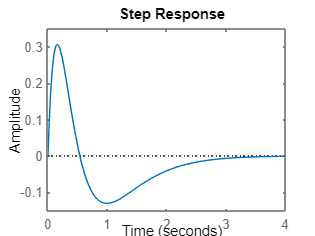


% risposta al gradino
step(sys_cl)

% verifica che il sistema in retroazione ha gli autovalori richiesti
eig(sys_cl)

ans =    -6.0000
   -3.0000
   -2.0000


% osservatore di ordine ridotto
po = [-1+1j, -1-1j]

po =   -1.0000 + 1.0000i  -1.0000 - 1.0000i



T = [C; 0,1,0; 0,0,1]

T =      2     1     2
     0     1     0
     0     0     1



Abar = T*A/T

Abar =      3     1   -14
     1     1    -2
     0     0    -6


Bbar = T*A

Bbar =      6     4    -8
     2     2     0
     0     0    -6


Cbar = C/T

Cbar =      1     0     0



Ad = Abar(2:3, 2:3)'

Ad =      1     0
    -2    -6


Bd = (Cbar(1)*Abar(1, 2:3))'

Bd =      1
   -14


kd = place(Ad,Bd,po)

kd =     0.7917    0.2708



L = kd'

L =     0.7917
    0.2708


% Verifico che gli autovalori sono quelli richiesti
F = Abar(2:3, 2:3) - L*Cbar(1)*Abar(1, 2:3)

F =     0.2083    9.0833
   -0.2708   -2.2083


eig(F)

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i
